# Hands-On: Spectral Factorization

## Introduction

In this live script, we offer a few examples of solving, using MATLAB code, simple problems involving computation of the **power spectra** of stationary stochastic processes, the **spectral factorization** and the so-called **canonical spectral factorization**.

What you will learn:

- How to cope with a spectral factorization problem using MATLAB;

- How to manage a spectrum of a stochastic proces with the aim to obtain a canonical spectral factorization;

- How to evaluate the autocorrelation function of a stationary stochastic process, given its complex spectrum, and viceversa.

- What is a so-called **whitening filter** and how to obtain such a peculiar LTI system, given a canonical spectral factorization.

clear variables
close all
clc

sympref('HeavisideAtOrigin', 1); % we will using the Symbolic Toolbox

## **A Stationary Stochastic Process from a White Noise Response of an LTI Filter **

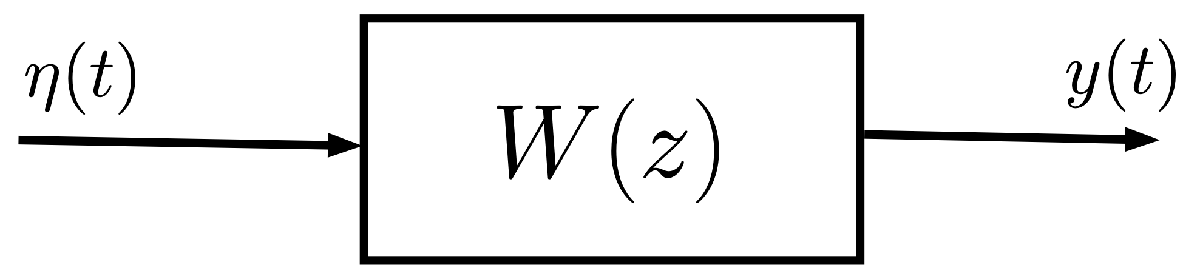

Considere a stationary stochastic process $y(t)$, generated by an LTI dynamic system with transfer function			

		
$$W(z) = \displaystyle \frac{1}{z-0.5}$$


and white noise $\eta(t)$ as its input. Assuming that  $\eta(t)$ has a zero-mean and a unit variance, find the power spectrum $\Gamma_y(\omega)$ and the autocorrelation function $\gamma_y(\tau)$ of $y(t)$.

### Solution

Since $y(t)$ is the output of the LTI system $W(z)$ (the filter) and the input is the unit-variance and zero-mean white noise $\eta(t)$, then the spectrum $\Phi(z)$ can be expressed as


$$\Phi_{y}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \Phi_{\eta}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot 1 = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) $$


syms z n sigma2_eta

Wz = 1/(z-0.5)  % the LTI system

$$Wz = \frac{1}{z-\frac{1}{2}}$$


sigma2_eta = 1; % the variance of the white noise 


Thus the process spectrum is

W_z1 = subs(Wz, z, (z^(-1)))

$$W\_z1 = \frac{1}{\frac{1}{z}-\frac{1}{2}}$$

PhiZ = Wz*W_z1*sigma2_eta   

$$PhiZ = \frac{1}{\left(\frac{1}{z}-\frac{1}{2}\right)\,\left(z-\frac{1}{2}\right)}$$

Evaluating for $z=e^{i\,\omega$ we obtain $\Gamma_y(\omega)$

syms omega
Gamma_y = subs(PhiZ, z, exp(1i*omega))

$$Gamma\_y = \frac{1}{\left({\mathrm{e}}^{-\omega \,\mathrm{i}}-\frac{1}{2}\right)\,\left({\mathrm{e}}^{\omega \,\mathrm{i}}-\frac{1}{2}\right)}$$

Rewrite $\Gamma_y(\omega)$ exploiting the Euler's formula	 				

			
$$e^{i\,\omega} = \cos \omega +i\,\sin \omega$$


where $i$ is the imaginary unit. Thus


$$\cos \omega = \displaystyle \frac{e^{i\,\omega}+e^{-i\,\omega}}{2}\quad $$


Gamma_y = simplify(rewrite(Gamma_y, "cos"))

$$Gamma\_y = -\frac{4}{4\,\cos\left(\omega \right)-5}$$

The spectrum is

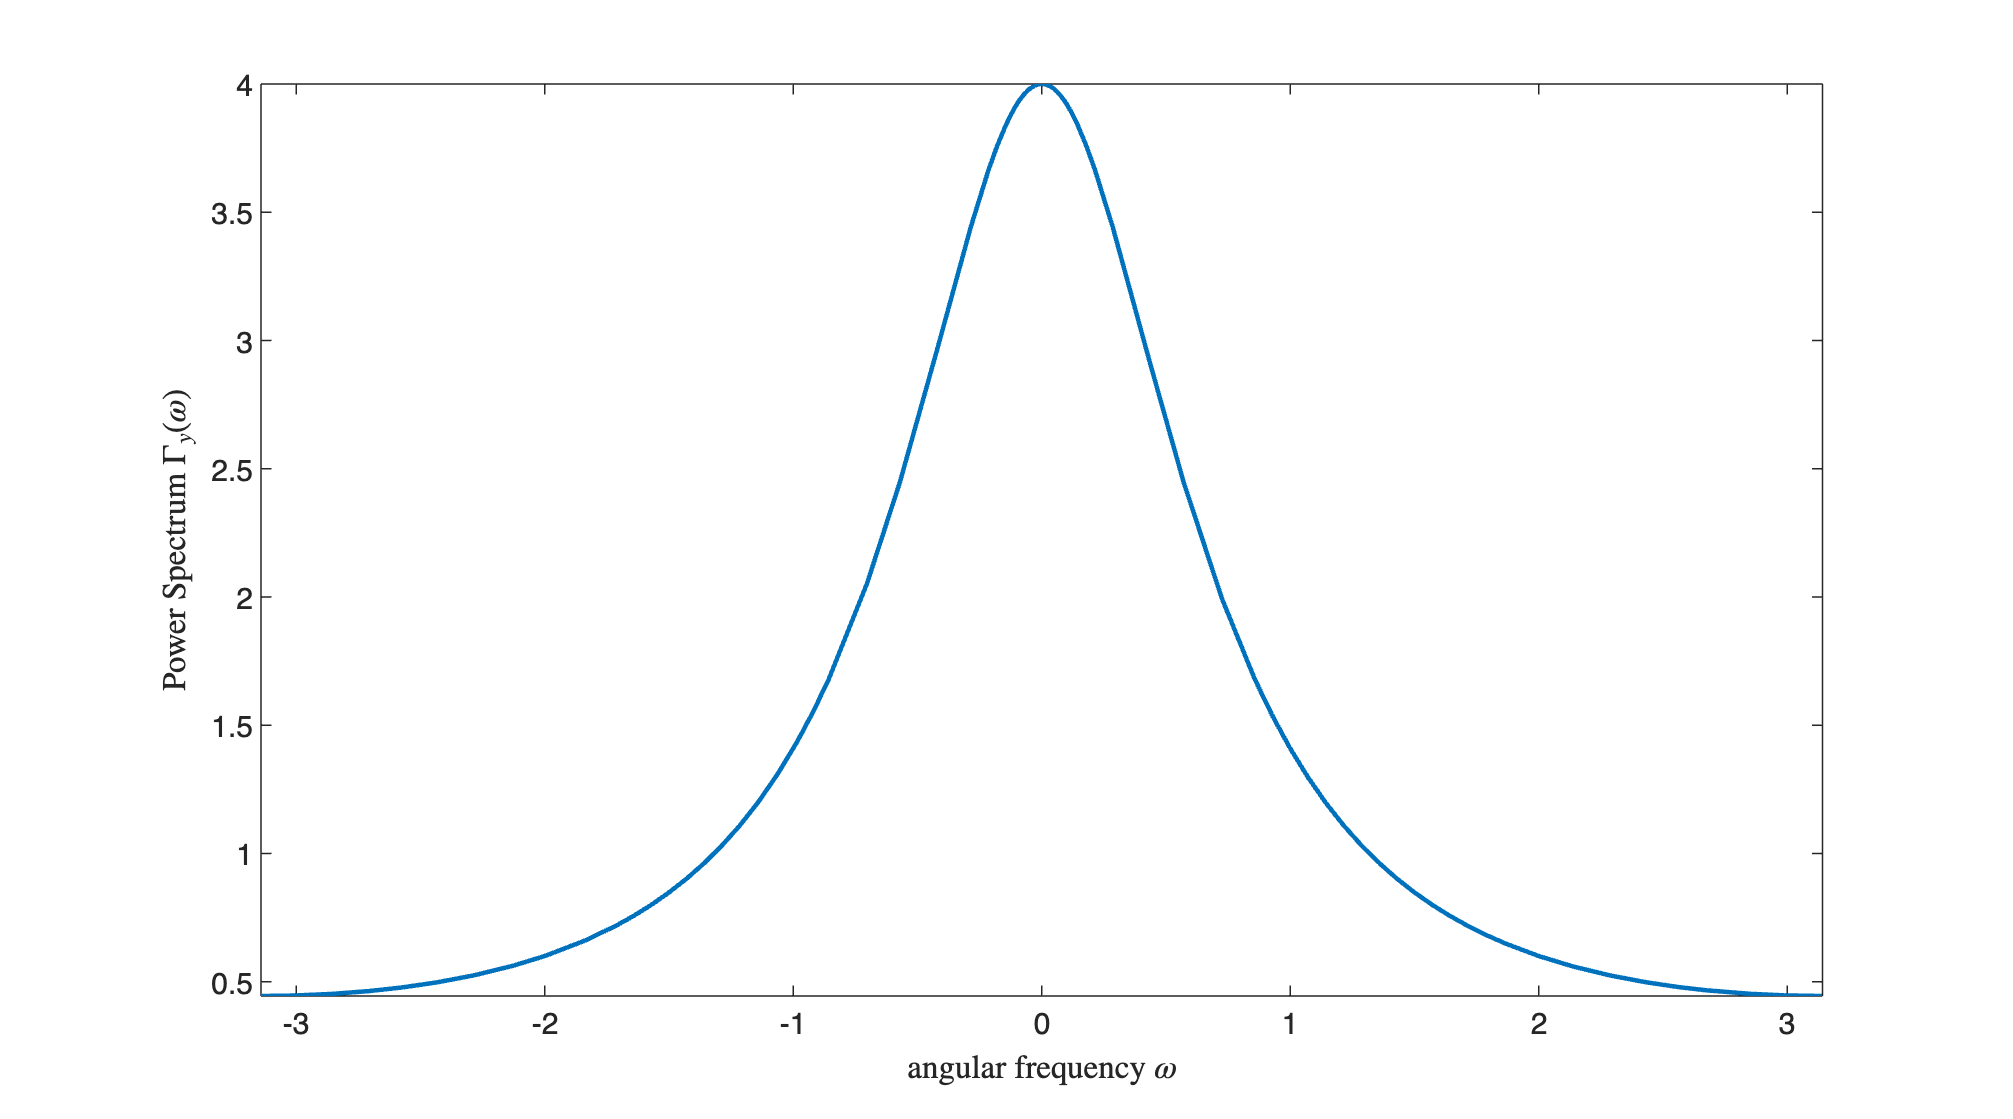

figure('Units','normalized','Position',[0.1,0.1,0.9,0.8]);
fplot(gca, Gamma_y, [-pi, pi], 'LineStyle','-','LineWidth',1.5);
xlabel('angular frequency $\omega$', 'Interpreter','latex');
ylabel('Power Spectrum $\Gamma_{y}(\omega)$', 'Interpreter','latex')

### Q&A

- Given the expression of $W(z)$,  to which family of rational spectrum processes does the analyzed stochastic process belong?

- Is the spectral factorisation canonical or not? Why? If not, what can the canonical spectral factorisation be?

- What is the variance of the process?

- Given the spectral canonical factorization, what is the autocorrelation function?

## A Spectral Shaping Filter (work-in-progress)

Suppose we want to **generate a stationary stochastic process** characterised by the following **power spectrum**


$$\Gamma_{y}(\omega) = \displaystyle \frac{5+4\, \cos\omega}{10+6\,\cos \omega} \qquad \omega \in \left[ -\pi\,,\; +\pi \right]$$


by **filtering** unit-variance and zero-mean white noise $\eta(t)$ with an asymptotically stable LTI system 

			

Find the transfer function $W(z)$ of the filter. Is $W(z)$ unique?

Let us define the angular frequency $\omega$ as symbolic variable, and then assign the spectrum

syms omega
Gamma_y = (5+4*cos(omega))/(10+6*cos(omega))

Rewrite $\Gamma_y(\omega)$ exploiting the Euler's formula	 				

			
$$e^{i\,\omega} = \cos \omega +i\,\sin \omega$$


where $i$ is the imaginary unit. Thus


$$\cos \omega = \displaystyle \frac{e^{i\,\omega}+e^{-i\,\omega}}{2}\$$


and we obtain

Gamma_y = rewrite(Gamma_y, "exp")

Now, replacing  $e^{i\,\omega}$ with the complex variable $z$ we obtain the expression of the desired complex spectrum $\Phi(z)$, as Z-transform of the autocorrelation function $\gamma_y(\tau)$	

syms z

$$Gamma\_y = \frac{4\,\cos\left(\omega \right)+5}{6\,\cos\left(\omega \right)+10}$$


PhiZ = subs(Gamma_y, exp(i*omega), z)

Since $y(t)$ is the output of the LTI system $W(z)$ (the filter) and the input is the unit-variance and zero-mean white noise $\eta(t)$, then the spectrum $\Phi(z)$ can be expressed as


$$\Phi_{y}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \Phi_{\eta}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot 1 = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) $$



[numZ, denZ] = numden(PhiZ)

$$Gamma\_y = \frac{2\,{\mathrm{e}}^{-\omega \,\mathrm{i}}+2\,{\mathrm{e}}^{\omega \,\mathrm{i}}+5}{3\,{\mathrm{e}}^{-\omega \,\mathrm{i}}+3\,{\mathrm{e}}^{\omega \,\mathrm{i}}+10}$$

$$PhiZ = \frac{2\,z+\frac{2}{z}+5}{3\,z+\frac{3}{z}+10}$$

$$numZ = 2\,z^{2}+5\,z+2$$

$$denZ = 3\,z^{2}+10\,z+3$$

" work in progress"	 